# Task 1:

clear all
clc

## a)

% First enter the transfer function G(s)
numG = 1;
denG = conv ( conv ( [1 0], [1 1] ), [0.2 1] );
% Convert to state-space model
[ Ag, Bg, Cg, Dg ] = tf2ss ( numG, denG );
% Check the controllability and observability of the system
    system_order = length(Ag) % equals "3"

system_order = 3

M = ctrb(Ag, Bg);
rank_of_M = rank(M) % equals "3"

rank_of_M = 3

N = obsv(Ag, Cg);
rank_of_N = rank(N) % equals "3"

rank_of_N = 3

% Compute the poles of a second-order system
damping = 0.707;
wn = 3;
[ num2, den2 ] = ord2 (wn, damping);
% Select desired poles to include poles of the second-order system
dominant = roots(den2);
desiredpoles = [dominant' 10 * real( dominant(1) ) ];
% Compute the controller gain K
K = acker (Ag, Bg, desiredpoles);
% Compute the closed-loop state variable feedback system
Asf = Ag - Bg * K; Bsf = Bg; Csf = Cg; Dsf = 0;
[numsf, densf] = ss2tf (Asf, Bsf, Csf, Dsf);
% Select observer poles to be 10 times faster than controller poles
observerpoles = 10 * desiredpoles;
% Compute the observer gain L
L = acker (Ag', Cg', observerpoles);
% Compute the closed-loop system with both controller and observer
Areg = [ (Ag - Bg * K) Bg * K; zeros( size(Ag) ) (Ag - L' * Cg) ];
Breg = [ Bg; zeros( size(Bg) ) ];
Creg = [ Cg zeros( size(Cg) ) ];
Dreg = 0;
[numreg, denreg] = ss2tf ( Areg, Breg, Creg, Dreg );
damp(denreg); 

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -2.12e+02                 1.00e+00       2.12e+02          4.71e-03    
 -2.12e+01 + 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -2.12e+01 - 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -2.12e+01                 1.00e+00       2.12e+01          4.71e-02    
 -2.12e+00 + 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    
 -2.12e+00 - 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    


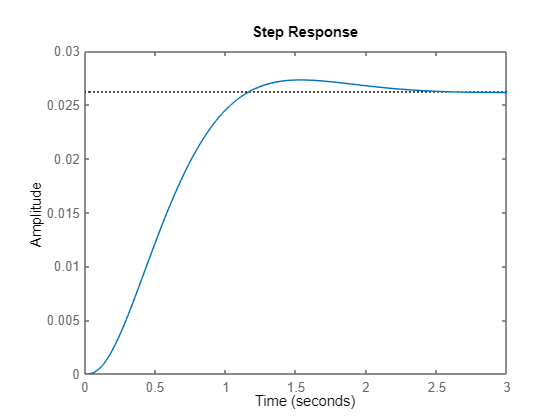

G=tf(numsf,densf);
step(numsf,densf);

stepinfo(G,'RiseTimeLimits',[0.1 0.9])

ans = struct with fields:
         RiseTime: 0.7242
    TransientTime: 2.0357
     SettlingTime: 2.0357
      SettlingMin: 0.0239
      SettlingMax: 0.0273
        Overshoot: 4.2749
       Undershoot: 0
             Peak: 0.0273
         PeakTime: 1.5416


K

K =    19.4520   93.9728  190.8900


desiredpoles2 = [dominant' 20 * real( dominant(1) ) ];
% Compute the controller gain K
K2 = acker (Ag, Bg, desiredpoles2);
% Compute the closed-loop state variable feedback system
Asf = Ag - Bg * K; Bsf = Bg; Csf = Cg; Dsf = 0;
[numsf2, densf2] = ss2tf (Asf, Bsf, Csf, Dsf);
% Select observer poles to be 10 times faster than controller poles
observerpoles2 = 10 * desiredpoles2;
% Compute the observer gain L
L2 = acker (Ag', Cg', observerpoles2);
% Compute the closed-loop system with both controller and observer
Areg2 = [ (Ag - Bg * K) Bg * K; zeros( size(Ag) ) (Ag - L2' * Cg) ];
Breg2 = [ Bg; zeros( size(Bg) ) ];
Creg2 = [ Cg zeros( size(Cg) ) ];
Dreg2 = 0;
[numreg2, denreg2] = ss2tf ( Areg2, Breg2, Creg2, Dreg2 );
damp(denreg2); 

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -4.24e+02                 1.00e+00       4.24e+02          2.36e-03    
 -2.12e+01 + 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -2.12e+01 - 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -2.12e+01                 1.00e+00       2.12e+01          4.71e-02    
 -2.12e+00 + 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    
 -2.12e+00 - 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    



G2=tf(numsf2,densf2);
step(numsf2,densf2);

stepinfo(G2,'RiseTimeLimits',[0.1 0.9])

ans = struct with fields:
         RiseTime: 0.7242
    TransientTime: 2.0357
     SettlingTime: 2.0357
      SettlingMin: 0.0239
      SettlingMax: 0.0273
        Overshoot: 4.2749
       Undershoot: 0
             Peak: 0.0273
         PeakTime: 1.5416


K2

K2 =    40.6620  183.9456  381.7800


In this example we can observe that the gain calculated with the regulator.m file is approximately 2 times smaller, than the gain of the initial system. Correspondingly the numbers obtained were: 40.66, 183,94 & 381.78 without regulator.m and 19.45, 93.97 & 190.89 with it. The change in gain has an influence on the position of the poles of the system. We know that as the gain continues to increase the location of closed-loop poles moves from the location of open-loop poles to the location of open-loop zeros. The overall dynamics of the system with and without regulator.m have not been significantly affected with the exception of frequency, which is directly related to the gain of the poles.

## b)

desiredpoles = [dominant' 4 * real( dominant(1) ) ];
% Compute the controller gain K.
K = acker (Ag, Bg, desiredpoles);
% Compute the closed-loop state variable feedback system.
Asf = Ag - Bg * K; Bsf = Bg; Csf = Cg; Dsf = 0;
[numsf, densf] = ss2tf (Asf, Bsf, Csf, Dsf);
% Select observer poles to be 10 times faster than controller.
observerpoles = 10 * desiredpoles;
% Compute observer gain L.
L = acker (Ag', Cg', observerpoles);
% Compute the closed-loop system with controller and observer.
Areg = [ (Ag - Bg * K) Bg * K; zeros( size(Ag) ) (Ag - L' *Cg) ];
Breg = [ Bg; zeros( size(Bg) ) ];
Creg = [ Cg zeros ( size(Cg) ) ];
Dreg = 0;
[numreg, denreg] = ss2tf ( Areg, Breg, Creg, Dreg );
damp (denreg);

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -8.48e+01                 1.00e+00       8.48e+01          1.18e-02    
 -2.12e+01 + 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -2.12e+01 - 2.12e+01i     7.07e-01       3.00e+01          4.71e-02    
 -8.48e+00                 1.00e+00       8.48e+00          1.18e-01    
 -2.12e+00 + 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    
 -2.12e+00 - 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    


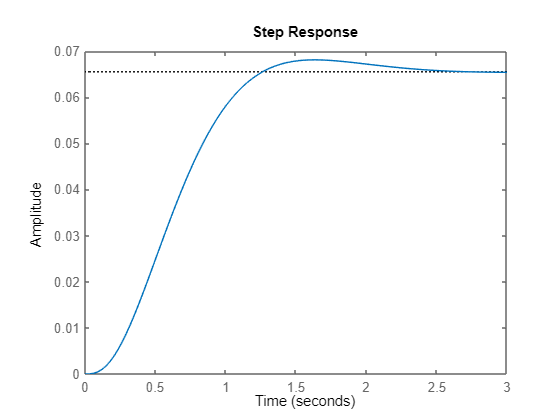

G2=tf(numsf,densf);
step(numsf,densf);

stepinfo(G2,'RiseTimeLimits',[0.1 0.9])

ans = struct with fields:
         RiseTime: 0.7647
    TransientTime: 2.1069
     SettlingTime: 2.1069
      SettlingMin: 0.0593
      SettlingMax: 0.0681
        Overshoot: 3.9657
       Undershoot: 0
             Peak: 0.0681
         PeakTime: 1.6284


K

K =     6.7260   39.9891   76.3560


Compared to the other 2 set ups, in this case the obtained gain K is smaller, therefore the poles are closer to the imaginary axis. In general the closer non-dominant poles are to the dominant pole, the more significant effect they have on the overall system performance. In particular in our case they resulted in higher rise time and peak time compared to the previous instances.

## c)

desiredpoles4 = [dominant' 10 * real( dominant(1) ) ];
% Compute the controller gain K.
K4 = acker (Ag, Bg, desiredpoles4);
% Compute the closed-loop state variable feedback system.
Asf = Ag - Bg * K; Bsf = Bg; Csf = Cg; Dsf = 0;
[numsf4, densf4] = ss2tf (Asf, Bsf, Csf, Dsf);
% Select observer poles to be 10 times faster than controller.
observerpoles4 = 20 * desiredpoles4;
% Compute observer gain L.
L4 = acker (Ag', Cg', observerpoles4);
% Compute the closed-loop system with controller and observer.
Areg4 = [ (Ag - Bg * K) Bg * K; zeros( size(Ag) ) (Ag - L4' *Cg) ];
Breg4 = [ Bg; zeros( size(Bg) ) ];
Creg4 = [ Cg zeros ( size(Cg) ) ];
Dreg4 = 0;
[numreg4, denreg4] = ss2tf ( Areg4, Breg4, Creg4, Dreg4 );
damp (denreg4);

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -4.24e+02                 1.00e+00       4.24e+02          2.36e-03    
 -4.24e+01 + 4.24e+01i     7.07e-01       6.00e+01          2.36e-02    
 -4.24e+01 - 4.24e+01i     7.07e-01       6.00e+01          2.36e-02    
 -8.48e+00                 1.00e+00       8.48e+00          1.18e-01    
 -2.12e+00 + 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    
 -2.12e+00 - 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    



G4=tf(numsf4,densf4);
step(numsf4,densf4);

stepinfo(G4,'RiseTimeLimits',[0.1 0.9])

ans = struct with fields:
         RiseTime: 0.7647
    TransientTime: 2.1069
     SettlingTime: 2.1069
      SettlingMin: 0.0593
      SettlingMax: 0.0681
        Overshoot: 3.9657
       Undershoot: 0
             Peak: 0.0681
         PeakTime: 1.6284


K4

K4 =    19.4520   93.9728  190.8900


In this case, by increasing the distance of the observer poles (or their "speed") the values in the original L matrix are significantly smaller (2.7848e+04, 1.6802e+03, 49.7040 vs 2.6104e+05, 7.3132e+03, 100.6080). When the observer poles are faster, the state estimation is more responsive to changes in the system's dynamics. This can be beneficial in some cases because it allows the controller to respond quickly to changes in the system and improve the system's performance. However, faster observer poles can also introduce noise amplification and sensitivity to modeling errors, which can degrade the system's stability and performance.

## d)

desiredpoles5 = [dominant' 10 * real( dominant(1) ) ];
% Compute the controller gain K.
K5 = acker (Ag, Bg, desiredpoles5);
% Compute the closed-loop state variable feedback system.
Asf = Ag - Bg * K; Bsf = Bg; Csf = Cg; Dsf = 0;
[numsf5, densf5] = ss2tf (Asf, Bsf, Csf, Dsf);
% Select observer poles to be 10 times faster than controller.
observerpoles5 = 4 * desiredpoles5;
% Compute observer gain L.
L5 = acker (Ag', Cg', observerpoles5);
% Compute the closed-loop system with controller and observer.
Areg5 = [ (Ag - Bg * K) Bg * K; zeros( size(Ag) ) (Ag - L5' *Cg) ];
Breg5 = [ Bg; zeros( size(Bg) ) ];
Creg5 = [ Cg zeros ( size(Cg) ) ];
Dreg5 = 0;
[numreg5, denreg5] = ss2tf ( Areg5, Breg5, Creg5, Dreg5 );
damp (denreg5);

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -8.48e+01                 1.00e+00       8.48e+01          1.18e-02    
 -8.48e+00 + 8.49e+00i     7.07e-01       1.20e+01          1.18e-01    
 -8.48e+00 - 8.49e+00i     7.07e-01       1.20e+01          1.18e-01    
 -8.48e+00                 1.00e+00       8.48e+00          1.18e-01    
 -2.12e+00 + 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    
 -2.12e+00 - 2.12e+00i     7.07e-01       3.00e+00          4.71e-01    



G5=tf(numsf5,densf5);
step(numsf5,densf5);

stepinfo(G5,'RiseTimeLimits',[0.1 0.9])

ans = struct with fields:
         RiseTime: 0.7647
    TransientTime: 2.1069
     SettlingTime: 2.1069
      SettlingMin: 0.0593
      SettlingMax: 0.0681
        Overshoot: 3.9657
       Undershoot: 0
             Peak: 0.0681
         PeakTime: 1.6284


K5

K5 =    19.4520   93.9728  190.8900


In this case observer gain L was equal to: 1.1431e+03 200.7434 19.1616. It’s lower than in the previous case, because the “speed” of observer poles was smaller. There were no changes in RiseTime, Overshoot, PeakTime and so on. On the other hand we can see changes in poles, damping, frequency and time constant.

## e)

for wn=3:-0.001:0
    [ num2, den2 ] = ord2 (wn, damping);
    dominant=roots(den2);
    desiredpoles = [dominant' 10 * real( dominant(1) ) ];
    K = acker (Ag, Bg, desiredpoles);

    if ((K(3)<10)&&(K(2)<10)&&(K(1)<10))
        wn
        K
        break
    end

end

wn = 1.1220

K =     3.5190    8.8439    9.9861


In this exercise we have shown that the maximum natural frequency omega n obtained while all the elements of matrix K are smaller than 10 is 1.122.